%% ===============================================================
%  STEP 3B - Analisis multi-escalon (5 s cada nivel de PWM)
%  Archivo: analisis_bomba_step3_multi_5s.m
%
%  Objetivo:
%    - Recorrer TODOS los escalones hacia arriba en la zona útil
%    - Para cada escalón:
%         * definir ventana [t_step - 0.5 s, t_step + 5 s]
%         * calcular y0, y_inf, K, tau
%    - Guardar resultados en una tabla
%    - Graficar K(PWM) y tau(PWM)
% ================================================================

clear; clc; close all;

%% 1) CONFIGURACIÓN
nombreArchivo   = 'datos_barrido_Com_N.csv';

PWM_MIN         = 120;   % zona útil (ajusta si quieres incluir otros)
PWM_IGNORE_FROM = 115;   % ignorar explícitamente 115 -> 120 (arranque)
PWM_IGNORE_TO   = 125;

T_step          = 5.0;   % [s] duración de cada nivel de PWM

T_pre_win       = 0.5;   % [s] ventana antes del escalón
T_post_win      = 5.0;   % [s] ventana después del escalón
T_regime_width  = 1.0;   % [s] para promedio de régimen (último 1 s)

%% 2) CARGAR DATOS
data   = readtable(nombreArchivo);
t_ms   = data.t_ms;
u_pwm  = data.PWM;
p_kPa  = data.Presion_kPa;
t_s    = t_ms / 1000.0;

Ts_prom = mean(diff(t_s));
fprintf('Ts promedio ≈ %.4f s (%.1f ms)\n', Ts_prom, Ts_prom*1000);

Ts promedio ≈ 0.0100 s (10.0 ms)



%% 3) SEGMENTAR EN TRAMOS DE PWM CONSTANTE
idxCambios = find(diff(u_pwm) ~= 0);
idxInicio  = [1; idxCambios + 1];
idxFin     = [idxCambios; length(u_pwm)];
nTramos    = numel(idxInicio);

fprintf('STEP 3B: se detectaron %d tramos de PWM constante.\n', nTramos);

STEP 3B: se detectaron 53 tramos de PWM constante.



%% 4) RECORRER TODOS LOS ESCALONES HACIA ARRIBA EN ZONA ÚTIL

% Vectores para guardar resultados
pwm0_list  = [];
pwm1_list  = [];
y0_list    = [];
yinf_list  = [];
du_list    = [];
dy_list    = [];
K_list     = [];
tau_list   = [];
tstep_list = [];

for k = 1:nTramos-1
    i1 = idxInicio(k);
    i2 = idxFin(k);
    j1 = idxInicio(k+1);
    j2 = idxFin(k+1);

    pwm_before = u_pwm(i1);
    pwm_after  = u_pwm(j1);

    % Solo ESCALONES HACIA ARRIBA
    if pwm_after <= pwm_before
        continue;
    end

    % Nivel FINAL en zona útil
    if pwm_after < PWM_MIN
        continue;
    end

    % Ignorar explícitamente el escalón de arranque 115 -> 120
    if pwm_before == PWM_IGNORE_FROM && pwm_after == PWM_IGNORE_TO
        fprintf('   ⛔ Ignorando escalon %g -> %g (umbral)\n', ...
                pwm_before, pwm_after);
        continue;
    end

    % Duración del tramo después del escalón (debe ser ≈ 5 s)
    dur_post = t_s(j2) - t_s(j1);
    if dur_post < (T_step - Ts_prom)
        continue;
    end

    % --- DATOS DEL ESCALÓN SELECCIONADO ---
    t_step = t_s(j1);

    t_ini_win = t_step - T_pre_win;
    t_fin_win = t_step + T_post_win;

    idx_window = find( t_s >= t_ini_win & t_s <= t_fin_win );
    if numel(idx_window) < 10
        continue;   % ventana demasiado corta → ignorar
    end

    t_win = t_s(idx_window);
    u_win = u_pwm(idx_window);
    p_win = p_kPa(idx_window);

    idx_before = find(t_win < t_step);
    idx_after  = find(t_win >= t_step);

    if isempty(idx_before) || numel(idx_after) < 5
        continue;
    end

    t_before = t_win(idx_before);
    p_before = p_win(idx_before);

    t_after  = t_win(idx_after);
    p_after  = p_win(idx_after);

    % --- y0: promedio en la ventana antes del escalón ---
    t_ini_y0 = t_step - T_pre_win;
    idx_y0   = find( t_before >= t_ini_y0 );
    if isempty(idx_y0)
        idx_y0 = 1:numel(t_before);
    end
    y0 = mean( p_before(idx_y0) );

    % --- y_inf: promedio en el último segundo de los 5 s ---
    t_ini_reg = t_step + (T_post_win - T_regime_width);
    t_fin_reg = t_step + T_post_win;
    idx_regime = find( t_after >= t_ini_reg & t_after <= t_fin_reg );
    if isempty(idx_regime)
        idx_regime = max(1, numel(t_after)-5) : numel(t_after);
    end
    y_inf = mean( p_after(idx_regime) );

    % --- Ganancia K ---
    du = pwm_after - pwm_before;
    dy = y_inf - y0;
    K  = dy / du;

    % --- Constante de tiempo tau (63.2%) ---
    t_resp = t_after;
    y_resp = p_after;
    frac = 1 - exp(-1);      % 0.632
    y_target = y0 + frac * dy;

    idxTau = [];
    if dy > 0
        idxTau = find(y_resp >= y_target, 1, 'first');
    elseif dy < 0
        idxTau = find(y_resp <= y_target, 1, 'first');
    end

    if isempty(idxTau)
        tau = NaN;
    else
        t_tau_abs = t_resp(idxTau);
        tau = t_tau_abs - t_step;
    end

    % Guardar resultados
    pwm0_list  = [pwm0_list; pwm_before];
    pwm1_list  = [pwm1_list; pwm_after];
    y0_list    = [y0_list;   y0];
    yinf_list  = [yinf_list; y_inf];
    du_list    = [du_list;   du];
    dy_list    = [dy_list;   dy];
    K_list     = [K_list;    K];
    tau_list   = [tau_list;  tau];
    tstep_list = [tstep_list; t_step];
end

%% 5) TABLA DE RESULTADOS

results = table( tstep_list, pwm0_list, pwm1_list, du_list, ...
                 y0_list, yinf_list, dy_list, K_list, tau_list, ...
    'VariableNames', {'t_step_s','PWM0','PWM1','DeltaPWM', ...
                      'y0_kPa','yinf_kPa','Deltay_kPa','K_kPa_por_PWM','tau_s'});

disp('=== RESULTADOS POR ESCALON ===');

=== RESULTADOS POR ESCALON ===


disp(results);

    t_step_s    PWM0    PWM1    DeltaPWM    y0_kPa     yinf_kPa    Deltay_kPa     K_kPa_por_PWM    tau_s
    ________    ____    ____    ________    _______    ________    ___________    _____________    _____

     132.01     125     130        5        -32.902    -33.027        -0.12536       -0.025071     0.08 
     137.01     130     135        5        -33.029    -33.344        -0.31502       -0.063004      3.9 
     142.01     135     140        5        -33.367    -33.683        -0.31588       -0.063176     0.22 
     147.01     140     145        5        -33.698    -33.894        -0.19613       -0.039225     0.17 
     152.01     145     150        5        -33.901     -33.98 

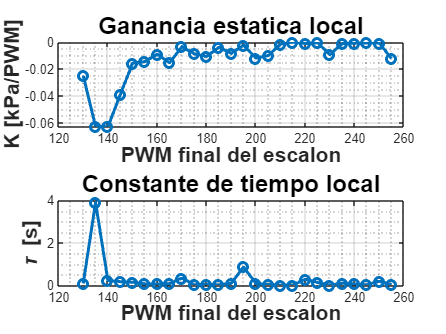


%% 6) GRAFICAS K(PWM) Y TAU(PWM)

LW   = 2.0;
FS   = 14;
FSbig = 16;

figure('Name','Parametros por escalon','Color','w');

subplot(2,1,1);
plot(pwm1_list, K_list, '-o', 'LineWidth', LW);
grid on; grid minor;
xlabel('PWM final del escalon','FontSize',FS,'FontWeight','bold');
ylabel('K [kPa/PWM]','FontSize',FS,'FontWeight','bold');
title('Ganancia estatica local','FontSize',FSbig,'FontWeight','bold');

subplot(2,1,2);
plot(pwm1_list, tau_list, '-o', 'LineWidth', LW);
grid on; grid minor;
xlabel('PWM final del escalon','FontSize',FS,'FontWeight','bold');
ylabel('\tau [s]','FontSize',FS,'FontWeight','bold');
title('Constante de tiempo local','FontSize',FSbig,'FontWeight','bold');